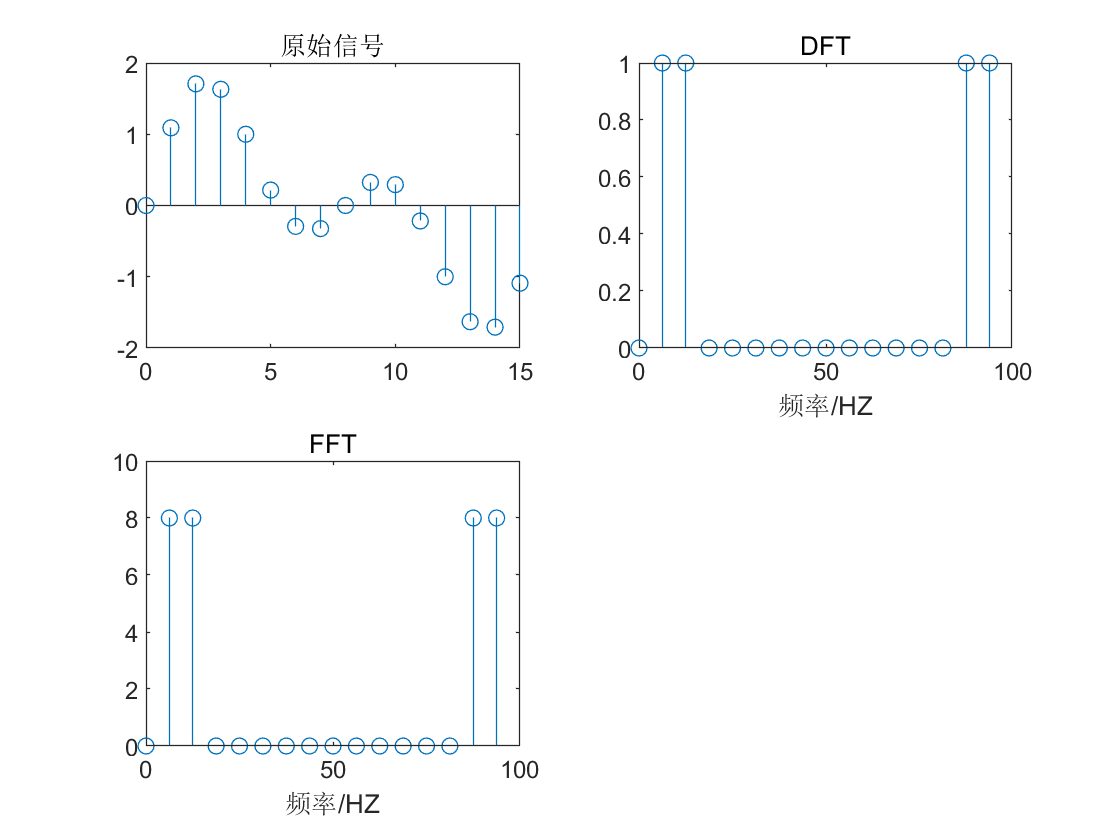

N=16;fs=100;
n=0:N-1;
f=n*fs/N;
xn=sin(n*pi/8)+sin(n*pi/4);
m=N;
a=zeros(1,m);b=zeros(1,m);
for k=0:m-1
    for ii=0:N-1
        a(k+1)=a(k+1)+2/N*xn(ii+1)*cos(2*pi*k*ii/N);
        b(k+1)=b(k+1)+2/N*xn(ii+1)*sin(2*pi*k*ii/N);
    end
    c(k+1)=sqrt(a(k+1)^2+b(k+1)^2);
end
Y=abs(fft(xn));
subplot(2,2,1);stem(n,xn);title('原始信号');
subplot(2,2,2);stem(f,c);title('DFT');xlabel('频率/HZ');
subplot(2,2,3);stem(f,Y);title('FFT');xlabel('频率/HZ');